clear;      % Removes all variables from the workspace
clc;        % Clears the Command Window
close all;  % Closes any hidden or external figure windows

raw_data = load("identification_data\rod_2_identification\matlab.mat");

% Unpack the loaded data into struct
angles = 15:15:120;

for i = 1:length(angles)
    var_name = sprintf('theta_2_%d_degrees', angles(i));
    data = raw_data.(var_name);

    expData(i).t = data.Time;
    expData(i).y_raw = data.Data;
    expData(i).u = zeros(size(data.Time));
    expData(i).initial_angle = angles(i);
end

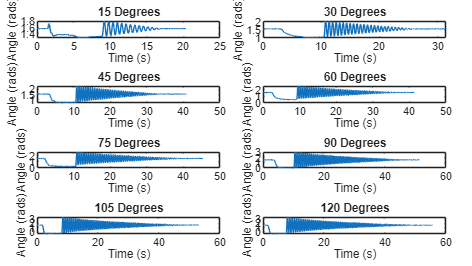

% Plotting raw data in time domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(angles)
    nexttile;
    plot(expData(i).t, expData(i).y_raw, "DisplayName", "Raw Data");
    title(sprintf('%d Degrees', angles(i)));
    ylabel("Angle (rads)");
    xlabel("Time (s)");
end

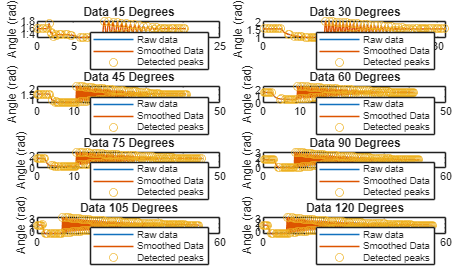

% Plot data with peak detection to truncate usefull data
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    % Filter out noise for peak detection
    fc = 5;     % Cut off frequency
    [b, a] = butter(3, fc/(fs/2), 'low');
    
    expData(i).y_smooth = filtfilt(b, a, expData(i).y_raw);

    % Find peaks
    minDist = round(0.3 * fs);
    [pMax, locMax] = findpeaks(expData(i).y_smooth, 'MinPeakDistance', minDist);
    [pMin, locMin] = findpeaks(-expData(i).y_smooth, 'MinPeakDistance', minDist);
    peak_indices = sort([locMax; locMin]);
    
    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t, expData(i).y_raw, 'DisplayName', 'Raw data');
    hold on;
    plot(expData(i).t, expData(i).y_smooth, 'DisplayName', 'Smoothed Data');
    plot(expData(i).t(peak_indices), expData(i).y_smooth(peak_indices), 'o', 'DisplayName', 'Detected peaks');
    
    legend;
    title(sprintf('Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

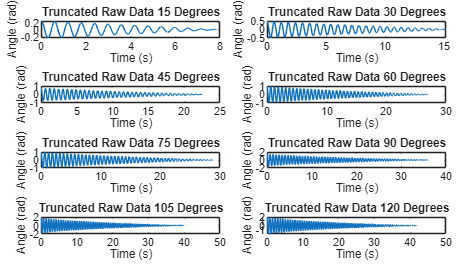

% Set indices for truncated data
expData(1).start_index = 919;
expData(1).end_index = 1703;

expData(2).start_index = 1078;
expData(2).end_index = 2594;

expData(3).start_index = 1089;
expData(3).end_index = 3339;

expData(4).start_index = 955;
expData(4).end_index = 3643;

expData(5).start_index = 1091;
expData(5).end_index = 3969;

expData(6).start_index = 1051;
expData(6).end_index = 4656;

expData(7).start_index = 851;
expData(7).end_index = 4857;

expData(8).start_index = 802;
expData(8).end_index = 4984;

for i = 1:length(angles)
    expData(i).y_id = expData(i).y_raw(expData(i).start_index:expData(i).end_index);
    expData(i).y_id = expData(i).y_id - mean(expData(i).y_raw(expData(i).end_index + 1:end));
    expData(i).t_id = expData(i).t(expData(i).start_index:expData(i).end_index);
    expData(i).t_id = expData(i).t_id - expData(i).t_id(1);
    expData(i).u_id = zeros(length(expData(i).y_id), 1);
end

% Plot truncated data time and frequency domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t_id, expData(i).y_id);

    title(sprintf('Truncated Raw Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

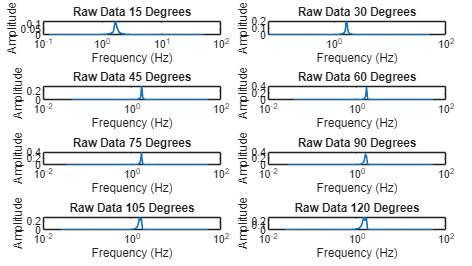

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Calc sampling period and frequency
    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    data_length = length(expData(i).y_id);

    % Compute the FFT
    y_fft = fft(expData(i).y_id);
    
    % Compute the two-sided spectrum P2
    P2 = abs(y_fft / data_length);
    
    % Compute the single-sided spectrum P1 based on P2
    P1 = P2(1:floor(data_length/2)+1);
    
    % Multiply by 2 to conserve energy (excluding DC and Nyquist frequencies)
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Define the frequency domain f (up to the Nyquist frequency)
    f = fs * (0:floor(data_length/2)) / data_length;
    
    nexttile;
    plot(f, P1, 'LineWidth', 1.2);
    
    title(sprintf('Raw Data %d Degrees', angles(i)));
    xlabel("Frequency (Hz)");
    ylabel("Amplitude");
    xscale('log')
end

%% Identification setup - Coulomb baseline + tail-only multistart low-velocity damping

% This section assumes that the data-cleaning section has already created:
%
%   expData(i).y_id
%   expData(i).t_id
%   expData(i).u_id
%   expData(i).initial_angle
%
% Do not change the data-cleaning section.

idxEst = [1 3 5 7];  % 15, 45, 75, 105 degrees
idxVal = [2 4 6 8];  % 30, 60, 90, 120 degrees

rng(1);  % for repeatable multi-start results

% Use sampling time from cleaned data.
Ts = expData(1).t_id(2) - expData(1).t_id(1);

% Check that all experiments have approximately the same sampling time.
for i = 1:numel(expData)
    Ts_i = expData(i).t_id(2) - expData(i).t_id(1);

    if abs(Ts_i - Ts) > 1e-9
        error('Experiment %d has a different sampling time.', i);
    end
end

%% User settings

% Small-oscillation threshold.
% This should be chosen around the region where your model visibly fails.
tailAmplitudeThreshold = 0.25;   % rad

% Minimum amount of data required after the automatic tail start.
minTailDuration = 3.0;           % seconds

% Number of random starts for the tail-only low-velocity damping fit.
numMultiStarts = 30;

%% Build full iddata objects

z = buildPendulumIdData(expData, Ts);

z_est = merge(z{idxEst});
z_val = merge(z{idxVal});

z_est.Name = 'Full estimation data';
z_val.Name = 'Full validation data';

%% ========================================================================
%  PART 1: Estimate Coulomb-viscous model on full data
%  ========================================================================

FileNameCoulomb = 'pendulum_rod_2_model_coulomb';
OrderCoulomb = [1 1 2];  % [outputs inputs states]
Ts_model = 0;            % continuous-time model

if isempty(which(FileNameCoulomb))
    error('MATLAB cannot find "%s.m". Make sure it is on the MATLAB path.', FileNameCoulomb);
end

[p0_coulomb, guessInfoCoulomb] = estimatePassivePendulumInitialGuessCoulomb(expData, idxEst, Ts);

fprintf('\nInitial Coulomb parameter guesses:\n');


Initial Coulomb parameter guesses:


fprintf('p_b2_init  = %.6g  [1/s]\n',     p0_coulomb(1));

p_b2_init  = 0.197115  [1/s]


fprintf('p_g2_init  = %.6g  [1/s^2]\n',   p0_coulomb(2));

p_g2_init  = 105.948  [1/s^2]


fprintf('p_c2_init  = %.6g  [rad/s^2]\n', p0_coulomb(3));

p_c2_init  = 0.52974  [rad/s^2]


fprintf('eps_v_init = %.6g  [rad/s]\n\n', p0_coulomb(4));

eps_v_init = 0.03  [rad/s]




disp(guessInfoCoulomb);

    ExperimentIndex    DominantFrequency_Hz    p_b2_guess    p_g2_guess    p_c2_guess    eps_v_guess
    _______________    ____________________    __________    __________    __________    ___________

           1                  1.6561            0.56926        108.35       0.54175       0.019404  
           3                  1.6437            0.21831        106.67       0.53337           0.03  
           5                  1.6325            0.17592        105.22       0.52611           0.03  
           7                  1.4974            0.13693        88.521       0.44261           0.03  




x0_est = estimateInitialStates(expData, idxEst);

% Coulomb parameter vector:
%
%   p(1) = p_b2
%   p(2) = p_g2
%   p(3) = p_c2
%   p(4) = eps_v
%
% Keep eps_v fixed. It is a numerical smoothing parameter.
parameterFixedCoulomb = [
    false   % p_b2
    false   % p_g2
    false   % p_c2
    true    % eps_v
];

model_coulomb = createRod2GreyBoxModelCoulomb( ...
    FileNameCoulomb, OrderCoulomb, p0_coulomb, x0_est, Ts_model, ...
    parameterFixedCoulomb, ...
    true);  % estimate initial velocity?

optCoulomb = nlgreyestOptions;
optCoulomb.Display = 'on';
optCoulomb.SearchOptions.MaxIterations = 150;

estimated_model_coulomb = nlgreyest(z_est, model_coulomb, optCoulomb);

disp('Estimated Coulomb-viscous model:');

Estimated Coulomb-viscous model:


present(estimated_model_coulomb);


estimated_model_coulomb =

Continuous-time nonlinear grey-box model defined by 'pendulum_rod_2_model_coulomb' (MATLAB file):

   dx/dt = F(t, x(t), u(t), p1, ..., p4)
    y(t) = H(t, x(t), u(t), p1, ..., p4) + e(t)

 with 1 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 4).

 Inputs:
    u(1)  u(t) [-]
 States:                       Initial value
    x(1)  theta(t) [rad]         xinit@exp1    0.245596   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.763433   (fixed) in [-Inf, Inf]
                                 xinit@exp1    0.331074   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.695447   (fixed) in [-Inf, Inf]
    x(2)  theta_dot(t) [rad/s]   xinit@exp1    0.331074   (estimated) in [-Inf, Inf]
                                 xinit@exp2    0.695447   (estimated) in [-Inf, Inf]
                                 xinit@exp3    0.965531   (estimated) in [-Inf, Inf]
                                 xinit@exp4   -0.66


p_hat_coulomb = getParameterVector(estimated_model_coulomb);

fprintf('\nEstimated Coulomb-viscous parameters:\n');


Estimated Coulomb-viscous parameters:


fprintf('p_b2  = %.8g  [1/s]\n',     p_hat_coulomb(1));

p_b2  = 0.067215491  [1/s]


fprintf('p_g2  = %.8g  [1/s^2]\n',   p_hat_coulomb(2));

p_g2  = 112.03277  [1/s^2]


fprintf('p_c2  = %.8g  [rad/s^2]\n', p_hat_coulomb(3));

p_c2  = 0.24687499  [rad/s^2]


fprintf('eps_v = %.8g  [rad/s]\n',   p_hat_coulomb(4));

eps_v = 0.03  [rad/s]


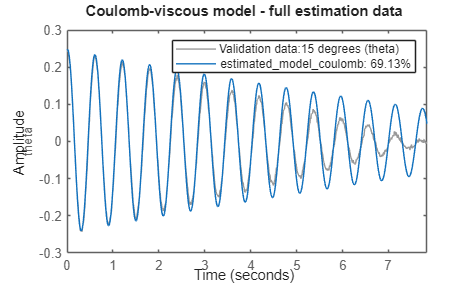


figure;
compare(z_est, estimated_model_coulomb);
title('Coulomb-viscous model - full estimation data');

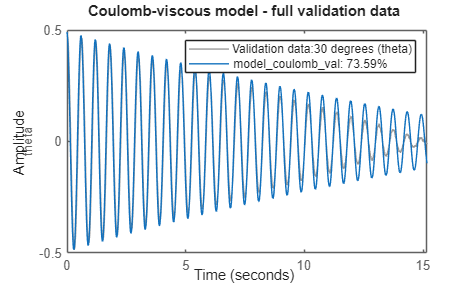


x0_val = estimateInitialStates(expData, idxVal);

model_coulomb_val = createRod2GreyBoxModelCoulomb( ...
    FileNameCoulomb, OrderCoulomb, p_hat_coulomb, x0_val, Ts_model, ...
    [true true true true], ...
    false);

figure;
compare(z_val, model_coulomb_val);
title('Coulomb-viscous model - full validation data');


%% ========================================================================
%  PART 2: Create tail-only data for small-oscillation fitting
%  ========================================================================

tailData = createTailOnlyData(expData, tailAmplitudeThreshold, minTailDuration, Ts);

Experiment 15 degrees: tail starts at 0.020 s, index 3, duration 7.820 s
Experiment 30 degrees: tail starts at 7.200 s, index 721, duration 7.960 s
Experiment 45 degrees: tail starts at 14.200 s, index 1421, duration 8.300 s
Experiment 60 degrees: tail starts at 18.260 s, index 1827, duration 8.620 s
Experiment 75 degrees: tail starts at 20.770 s, index 2078, duration 8.010 s
Experiment 90 degrees: tail starts at 28.040 s, index 2805, duration 8.010 s
Experiment 105 degrees: tail starts at 30.900 s, index 3091, duration 9.160 s
Experiment 120 degrees: tail starts at 32.860 s, index 3287, duration 8.960 s


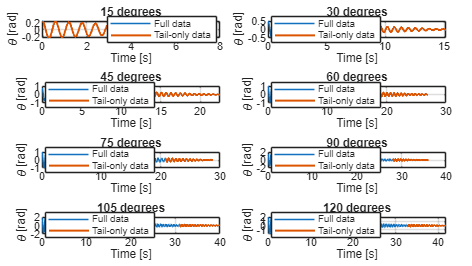


figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:numel(tailData)
    nexttile;
    plot(expData(i).t_id, expData(i).y_id, 'DisplayName', 'Full data');
    hold on;
    plot(tailData(i).t_id + tailData(i).original_t_start, ...
         tailData(i).y_id, ...
         'LineWidth', 1.5, ...
         'DisplayName', 'Tail-only data');
    grid on;
    title(sprintf('%d degrees', expData(i).initial_angle));
    xlabel('Time [s]');
    ylabel('\theta [rad]');
    legend('Location', 'best');
end


z_tail = buildPendulumIdData(tailData, Ts);

z_tail_est = merge(z_tail{idxEst});
z_tail_val = merge(z_tail{idxVal});

z_tail_est.Name = 'Tail-only estimation data';
z_tail_val.Name = 'Tail-only validation data';

%% ========================================================================
%  PART 3: Tail-only low-velocity damping model with multi-start
%  ========================================================================

FileNameLowVel = 'pendulum_rod_2_model_lowvel_damping';
OrderLowVel = [1 1 2];  % [outputs inputs states]

if isempty(which(FileNameLowVel))
    error('MATLAB cannot find "%s.m". Make sure it is on the MATLAB path.', FileNameLowVel);
end

p0_lowvel_base = createLowVelocityInitialGuessFromCoulomb( ...
    p_hat_coulomb, expData, idxEst, Ts);

fprintf('\nBase initial low-velocity damping parameter guesses from Coulomb result:\n');


Base initial low-velocity damping parameter guesses from Coulomb result:


printLowVelocityParameters(p0_lowvel_base);

p_b2     = 0.067215491  [1/s]
p_g2     = 112.03277  [1/s^2]
p_c2     = 0.24687499  [rad/s^2]
p_b_low  = 0.13443098  [1/s]
v_b      = 0.15  [rad/s]
eps_v    = 0.02  [rad/s]



% Parameter vector:
%
%   p(1) = p_b2
%   p(2) = p_g2
%   p(3) = p_c2
%   p(4) = p_b_low
%   p(5) = v_b
%   p(6) = eps_v
%
% Tail-only pass:
%   estimate p_b2, p_c2, p_b_low, v_b
%   fix p_g2 and eps_v
%
% Reason:
%   The tail problem is a friction problem, not a gravity/frequency problem.
parameterFixedTail = [
    false   % p_b2
    true    % p_g2
    false   % p_c2
    false   % p_b_low
    false   % v_b
    true    % eps_v
];

x0_tail_est = estimateInitialStates(tailData, idxEst);

optTail = nlgreyestOptions;
optTail.Display = 'off';
optTail.SearchOptions.MaxIterations = 200;

bestTailModel = [];
bestTailParameters = [];
bestTailLoss = Inf;

multiStartResults = table( ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    zeros(numMultiStarts,1), ...
    false(numMultiStarts,1), ...
    'VariableNames', {'StartNumber', 'Loss', 'p_b2', 'p_g2', 'p_c2', 'p_b_low', 'v_b', 'Converged'} ...
);

fprintf('\nRunning %d multi-start tail-only fits...\n', numMultiStarts);


Running 30 multi-start tail-only fits...



for startNumber = 1:numMultiStarts

    if startNumber == 1
        p0_trial = p0_lowvel_base;
    else
        p0_trial = randomizeLowVelocityInitialGuess(p0_lowvel_base);
    end

    try
        model_trial = createRod2GreyBoxModelLowVelDamping( ...
            FileNameLowVel, OrderLowVel, p0_trial, x0_tail_est, Ts_model, ...
            parameterFixedTail, ...
            true, ...
            p0_lowvel_base);  % use same bounds reference for all starts

        estimated_trial = nlgreyest(z_tail_est, model_trial, optTail);

        p_trial_hat = getParameterVector(estimated_trial);
        loss_trial = getModelLoss(estimated_trial);

        converged = isfinite(loss_trial);

        multiStartResults.StartNumber(startNumber) = startNumber;
        multiStartResults.Loss(startNumber) = loss_trial;
        multiStartResults.p_b2(startNumber) = p_trial_hat(1);
        multiStartResults.p_g2(startNumber) = p_trial_hat(2);
        multiStartResults.p_c2(startNumber) = p_trial_hat(3);
        multiStartResults.p_b_low(startNumber) = p_trial_hat(4);
        multiStartResults.v_b(startNumber) = p_trial_hat(5);
        multiStartResults.Converged(startNumber) = converged;

        fprintf('Start %02d/%02d: loss = %.6g, p_b_low = %.6g, v_b = %.6g\n', ...
            startNumber, numMultiStarts, loss_trial, p_trial_hat(4), p_trial_hat(5));

        if loss_trial < bestTailLoss
            bestTailLoss = loss_trial;
            bestTailModel = estimated_trial;
            bestTailParameters = p_trial_hat;
        end

    catch ME
        fprintf('Start %02d/%02d failed: %s\n', ...
            startNumber, numMultiStarts, ME.message);

        multiStartResults.StartNumber(startNumber) = startNumber;
        multiStartResults.Loss(startNumber) = Inf;
        multiStartResults.Converged(startNumber) = false;
    end
end

Start 01/30: loss = 2.95615e-05, p_b_low = 0.242774, v_b = 0.505447
Start 02/30: loss = 2.95636e-05, p_b_low = 0.235827, v_b = 0.500058
Start 03/30: loss = 2.95612e-05, p_b_low = 0.24191, v_b = 0.513086
Start 04/30: loss = 2.95607e-05, p_b_low = 0.244604, v_b = 0.500295
Start 05/30: loss = 2.95607e-05, p_b_low = 0.246674, v_b = 0.505984
Start 06/30: loss = 2.9562e-05, p_b_low = 0.244817, v_b = 0.508135


Start 07/30 failed: Initial value of parameter 3 is outside its bounds.
Value = 6.26992, Minimum = 0, Maximum = 4.9375


Start 08/30: loss = 2.95604e-05, p_b_low = 0.249319, v_b = 0.502331
Start 09/30: loss = 2.95626e-05, p_b_low = 0.233287, v_b = 0.485829
Start 10/30: loss = 2.9561e-05, p_b_low = 0.244094, v_b = 0.494974
Start 11/30: loss = 2.95606e-05, p_b_low = 0.248409, v_b = 0.498419
Start 12/30: loss = 2.96768e-05, p_b_low = 0.0324045, v_b = 0.126921
Start 13/30: loss = 2.9561e-05, p_b_low = 0.246663, v_b = 0.491918
Start 14/30: loss = 2.95611e-05, p_b_low = 0.246069, v_b = 0.491695
Start 15/30: loss = 2.96705e-05, p_b_low = 9.99823, v_b = 0.005
Start 16/30: loss = 2.95607e-05, p_b_low = 0.245378, v_b = 0.499037
Start 17/30: loss = 2.95615e-05, p_b_low = 0.243072, v_b = 0.505811
Start 18/30: loss = 2.95615e-05, p_b_low = 0.24286, v_b = 0.496645
Start 19/30: loss = 2.95625e-05, p_b_low = 0.22936, v_b = 0.491069
Start 20/30: loss = 2.96704e-05, p_b_low = 9.92468, v_b = 0.005
Start 21/30: loss = 2.95611e-05, p_b_low = 0.236514, v_b = 0.502787
Start 22/30: loss = 2.9561e-05, p_b_low = 0.242291, v_b = 0

Start 29/30 failed: Initial value of parameter 3 is outside its bounds.
Value = 7.66383, Minimum = 0, Maximum = 4.9375


Start 30/30: loss = 2.95616e-05, p_b_low = 0.251994, v_b = 0.483112



disp('Multi-start tail-only results:');

Multi-start tail-only results:


disp(sortrows(multiStartResults, 'Loss'));

    StartNumber       Loss          p_b2        p_g2      p_c2      p_b_low       v_b      Converged
    ___________    __________    __________    ______    _______    ________    _______    _________

         8          2.956e-05      0.020731    112.03    0.46574     0.24932    0.50233      true   
        23          2.956e-05      0.020735    112.03     0.4657     0.24766    0.50561      true   
        11         2.9561e-05      0.020303    112.03    0.46659     0.24841    0.49842      true   
        25         2.9561e-05       0.02028    112.03    0.46656     0.24504    0.50227      true   
         4         2.9561e-05      0.020109    112.03     0.4669      0.2446     0.5003      true   
        16         2


if isempty(bestTailModel)
    error('All multi-start tail-only fits failed.');
end

fprintf('\nBest tail-only low-velocity damping parameters:\n');


Best tail-only low-velocity damping parameters:


printLowVelocityParameters(bestTailParameters);

p_b2     = 0.020731495  [1/s]
p_g2     = 112.03277  [1/s^2]
p_c2     = 0.46574263  [rad/s^2]
p_b_low  = 0.24931857  [1/s]
v_b      = 0.50233111  [rad/s]
eps_v    = 0.02  [rad/s]


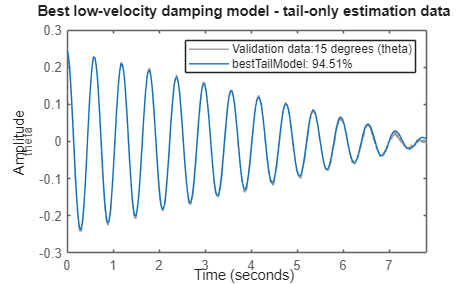


figure;
compare(z_tail_est, bestTailModel);
title('Best low-velocity damping model - tail-only estimation data');

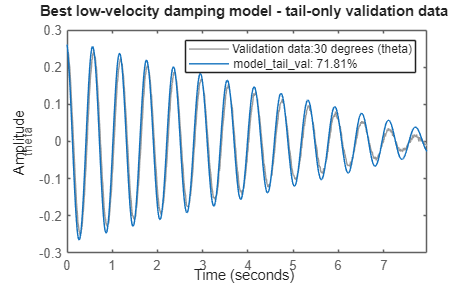


x0_tail_val = estimateInitialStates(tailData, idxVal);

model_tail_val = createRod2GreyBoxModelLowVelDamping( ...
    FileNameLowVel, OrderLowVel, bestTailParameters, x0_tail_val, Ts_model, ...
    [true true true true true true], ...
    false, ...
    p0_lowvel_base);

figure;
compare(z_tail_val, model_tail_val);
title('Best low-velocity damping model - tail-only validation data');


%% ========================================================================
%  PART 4: Full-data refinement with low-speed friction preserved
%  ========================================================================

% Use the tail-fitted friction as the starting point for a full-data model.
%
% Important:
%   Keep p_b_low and v_b fixed during this full-data refinement.
%
% Reason:
%   If they are free again, the full-data objective may remove the
%   low-speed damping because the large oscillations dominate the cost.
%
% Estimate only:
%   p_b2 and p_c2
%
% Keep fixed:
%   p_g2, p_b_low, v_b, eps_v
parameterFixedFullRefinement = [
    false   % p_b2
    true    % p_g2
    false   % p_c2
    true    % p_b_low
    true    % v_b
    true    % eps_v
];

x0_est = estimateInitialStates(expData, idxEst);

model_full_refine = createRod2GreyBoxModelLowVelDamping( ...
    FileNameLowVel, OrderLowVel, bestTailParameters, x0_est, Ts_model, ...
    parameterFixedFullRefinement, ...
    true, ...
    p0_lowvel_base);

optFullRefine = nlgreyestOptions;
optFullRefine.Display = 'on';
optFullRefine.SearchOptions.MaxIterations = 150;

estimated_model_lowvel_final = nlgreyest(z_est, model_full_refine, optFullRefine);

p_hat_lowvel_final = getParameterVector(estimated_model_lowvel_final);

fprintf('\nFinal low-velocity damping parameters after full-data refinement:\n');


Final low-velocity damping parameters after full-data refinement:


printLowVelocityParameters(p_hat_lowvel_final);

p_b2     = 0.010098776  [1/s]
p_g2     = 112.03277  [1/s^2]
p_c2     = 0.53171335  [rad/s^2]
p_b_low  = 0.24931857  [1/s]
v_b      = 0.50233111  [rad/s]
eps_v    = 0.02  [rad/s]



disp('Final low-velocity damping model:');

Final low-velocity damping model:


present(estimated_model_lowvel_final);


estimated_model_lowvel_final =

Continuous-time nonlinear grey-box model defined by 'pendulum_rod_2_model_lowvel_damping' (MATLAB file):

   dx/dt = F(t, x(t), u(t), p1, ..., p6)
    y(t) = H(t, x(t), u(t), p1, ..., p6) + e(t)

 with 1 input(s), 2 state(s), 1 output(s), and 2 free parameter(s) (out of 6).

 Inputs:
    u(1)  u(t) [-]
 States:                       Initial value
    x(1)  theta(t) [rad]         xinit@exp1    0.245596   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.763433   (fixed) in [-Inf, Inf]
                                 xinit@exp1    0.474448   (fixed) in [-Inf, Inf]
                                 xinit@exp2    0.633297   (fixed) in [-Inf, Inf]
    x(2)  theta_dot(t) [rad/s]   xinit@exp1    0.474448   (estimated) in [-Inf, Inf]
                                 xinit@exp2    0.633297   (estimated) in [-Inf, Inf]
                                 xinit@exp3   -0.385493   (estimated) in [-Inf, Inf]
                                 xinit@

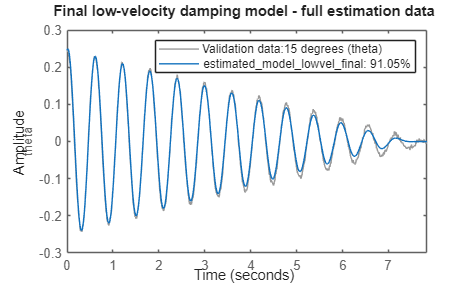


figure;
compare(z_est, estimated_model_lowvel_final);
title('Final low-velocity damping model - full estimation data');

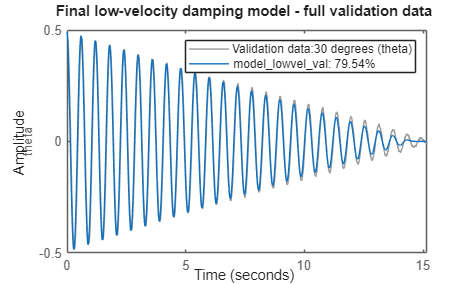


x0_val = estimateInitialStates(expData, idxVal);

model_lowvel_val = createRod2GreyBoxModelLowVelDamping( ...
    FileNameLowVel, OrderLowVel, p_hat_lowvel_final, x0_val, Ts_model, ...
    [true true true true true true], ...
    false, ...
    p0_lowvel_base);

figure;
compare(z_val, model_lowvel_val);
title('Final low-velocity damping model - full validation data');

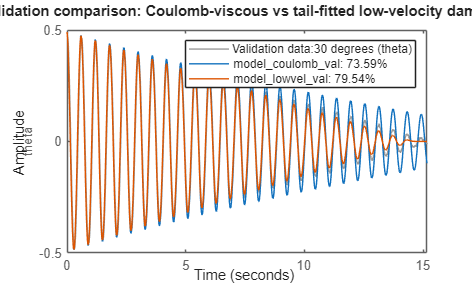


figure;
compare(z_val, model_coulomb_val, model_lowvel_val);
title('Validation comparison: Coulomb-viscous vs tail-fitted low-velocity damping');

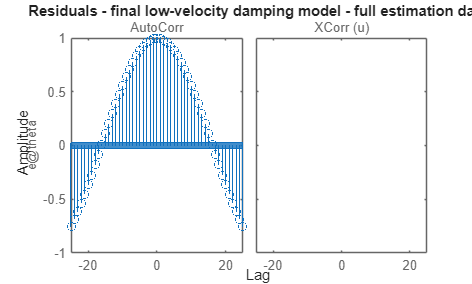


%% Residual analysis

figure;
resid(z_est, estimated_model_lowvel_final);
title('Residuals - final low-velocity damping model - full estimation data');

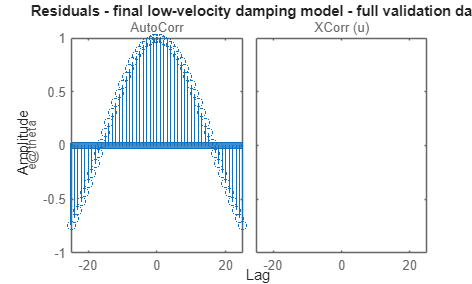


figure;
resid(z_val, model_lowvel_val);
title('Residuals - final low-velocity damping model - full validation data');

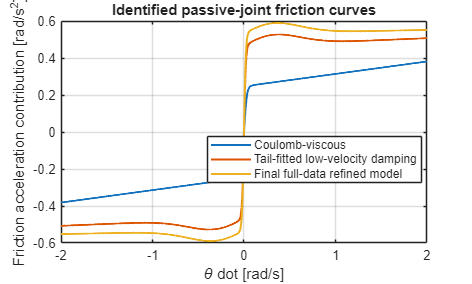

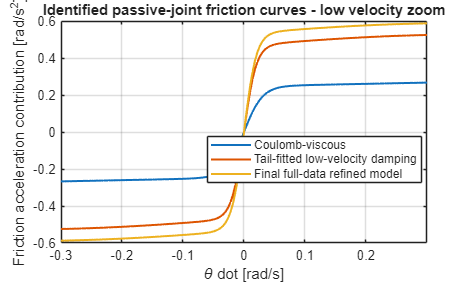

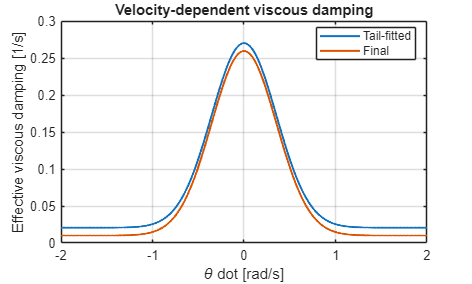


%% Plot friction curves

plotFrictionCurvesCoulombLowVel(p_hat_coulomb, bestTailParameters, p_hat_lowvel_final);



%% ========================================================================
%  Local helper functions
%  ========================================================================

function z = buildPendulumIdData(expData, Ts)

nExp = numel(expData);
z = cell(nExp, 1);

for i = 1:nExp

    y = expData(i).y_id(:);

    if isfield(expData, 'u_id')
        u = expData(i).u_id(:);
    else
        u = zeros(numel(y), 1);
    end

    if numel(y) ~= numel(u)
        error('Experiment %d has unequal y and u length.', i);
    end

    z{i} = iddata(y, u, Ts);

    z{i}.Name = sprintf('%d degrees', expData(i).initial_angle);
    z{i}.ExperimentName = sprintf('%d degrees', expData(i).initial_angle);

    z{i}.InputName = {'u'};
    z{i}.InputUnit = {'-'};

    z{i}.OutputName = {'theta'};
    z{i}.OutputUnit = {'rad'};

    z{i}.TimeUnit = 's';
    z{i}.Tstart = 0;
end

end


function tailData = createTailOnlyData(expData, amplitudeThreshold, minTailDuration, Ts)

tailData = expData;

minTailSamples = max(10, round(minTailDuration / Ts));

for i = 1:numel(expData)

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    n = numel(y);

    if n < minTailSamples
        error('Experiment %d is shorter than the requested minimum tail duration.', i);
    end

    startIdx = findAutomaticTailStart(y, amplitudeThreshold, minTailSamples, Ts);

    tailData(i).y_id = y(startIdx:end);
    tailData(i).t_id = t(startIdx:end) - t(startIdx);
    tailData(i).u_id = zeros(numel(tailData(i).y_id), 1);

    tailData(i).original_t_start = t(startIdx);
    tailData(i).tail_start_index = startIdx;

    fprintf('Experiment %d degrees: tail starts at %.3f s, index %d, duration %.3f s\n', ...
        expData(i).initial_angle, ...
        t(startIdx), ...
        startIdx, ...
        tailData(i).t_id(end));
end

end


function startIdx = findAutomaticTailStart(y, amplitudeThreshold, minTailSamples, Ts)

y = y(:);
n = numel(y);

% Use peak amplitudes of abs(theta) to estimate when the oscillation envelope
% has entered the small-amplitude region.
yAbs = abs(y);

minPeakDistance = max(1, round(0.25 / Ts));

[pk, locs] = findpeaks(yAbs, 'MinPeakDistance', minPeakDistance);

% Fallback if findpeaks does not find enough peaks.
if numel(pk) < 3
    candidates = find(yAbs < amplitudeThreshold);

    candidates = candidates(candidates <= n - minTailSamples + 1);

    if isempty(candidates)
        startIdx = max(1, n - minTailSamples + 1);
    else
        startIdx = candidates(1);
    end

    return;
end

% Find the first peak after which nearly all remaining peaks are below the
% amplitude threshold. Use 90% instead of 100% to avoid one noisy peak
% preventing a tail from being selected.
startIdx = [];

for k = 1:numel(pk)

    remainingPeaks = pk(k:end);
    fractionBelow = mean(remainingPeaks < amplitudeThreshold);

    enoughSamplesLeft = locs(k) <= n - minTailSamples + 1;

    if fractionBelow >= 0.90 && enoughSamplesLeft
        startIdx = locs(k);
        break;
    end
end

% Fallback: first sample where abs(theta) is below threshold and enough data
% remains.
if isempty(startIdx)
    candidates = find(yAbs < amplitudeThreshold);
    candidates = candidates(candidates <= n - minTailSamples + 1);

    if isempty(candidates)
        startIdx = max(1, n - minTailSamples + 1);
    else
        startIdx = candidates(1);
    end
end

% Safety.
startIdx = max(1, min(startIdx, n - minTailSamples + 1));

end


function x0 = estimateInitialStates(expData, idx)

nExp = numel(idx);

theta0 = zeros(1, nExp);
theta_dot0 = zeros(1, nExp);

for k = 1:nExp

    i = idx(k);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    theta0(k) = y(1);

    % Estimate initial velocity from the first few samples.
    Nfit = min(5, numel(y));

    coeff = polyfit(t(1:Nfit), y(1:Nfit), 1);
    theta_dot0(k) = coeff(1);
end

if any(~isfinite(theta0)) || any(~isfinite(theta_dot0))
    error('Initial state guesses contain NaN or Inf.');
end

x0 = [
    theta0;
    theta_dot0
];

end


function model = createRod2GreyBoxModelCoulomb( ...
    FileName, Order, p, x0, Ts_model, parameterFixed, estimateInitialVelocity)

Parameters = num2cell(p(:));

model = idnlgrey(FileName, Order, Parameters, x0, Ts_model);

nExp = size(x0, 2);

model = setinit(model, 'Name', {'theta'; 'theta_dot'});
model = setinit(model, 'Unit', {'rad'; 'rad/s'});

model = setinit(model, 'Minimum', {-Inf(1,nExp); -Inf(1,nExp)});
model = setinit(model, 'Maximum', { Inf(1,nExp);  Inf(1,nExp)});

model = setinit(model, 'Fixed', {
    true(1,nExp);
    repmat(~estimateInitialVelocity, 1, nExp)
});

paramNames = {
    'p_b2'
    'p_g2'
    'p_c2'
    'eps_v'
};

paramUnits = {
    '1/s'
    '1/s^2'
    'rad/s^2'
    'rad/s'
};

paramMin = [
    0
    0
    0
    1e-4
];

paramMax = [
    Inf
    Inf
    Inf
    0.05
];

parameterFixed = normalizeFixedVector(parameterFixed, numel(paramNames));

for j = 1:numel(paramNames)
    model.Parameters(j).Name = paramNames{j};
    model.Parameters(j).Unit = paramUnits{j};
    model.Parameters(j).Minimum = paramMin(j);
    model.Parameters(j).Maximum = paramMax(j);
    model.Parameters(j).Fixed = parameterFixed(j);
end

end


function model = createRod2GreyBoxModelLowVelDamping( ...
    FileName, Order, p, x0, Ts_model, parameterFixed, estimateInitialVelocity, boundsReference)

if nargin < 8 || isempty(boundsReference)
    boundsReference = p;
end

Parameters = num2cell(p(:));

model = idnlgrey(FileName, Order, Parameters, x0, Ts_model);

nExp = size(x0, 2);

model = setinit(model, 'Name', {'theta'; 'theta_dot'});
model = setinit(model, 'Unit', {'rad'; 'rad/s'});

model = setinit(model, 'Minimum', {-Inf(1,nExp); -Inf(1,nExp)});
model = setinit(model, 'Maximum', { Inf(1,nExp);  Inf(1,nExp)});

model = setinit(model, 'Fixed', {
    true(1,nExp);
    repmat(~estimateInitialVelocity, 1, nExp)
});

paramNames = {
    'p_b2'
    'p_g2'
    'p_c2'
    'p_b_low'
    'v_b'
    'eps_v'
};

paramUnits = {
    '1/s'
    '1/s^2'
    'rad/s^2'
    '1/s'
    'rad/s'
    'rad/s'
};

p_b2_ref    = max(abs(boundsReference(1)), 1e-6);
p_g2_ref    = max(abs(boundsReference(2)), 1e-6);
p_c2_ref    = max(abs(boundsReference(3)), 1e-8);
p_b_low_ref = max(abs(boundsReference(4)), p_b2_ref);
eps_ref     = max(abs(boundsReference(6)), 1e-4);

% Bounds are deliberately wider than before because the previous result
% suggested that the low-speed friction was still too weak.
%
% However, p_g2 remains tightly bounded/fixed because the issue is decay,
% not oscillation frequency.
paramMin = [
    0
    0.80*p_g2_ref
    0
    0
    0.005
    1e-4
];

paramMax = [
    max(20*p_b2_ref, p_b2_ref + 2.0)
    1.20*p_g2_ref
    max(20*p_c2_ref, p_c2_ref + 2.0)
    max([100*p_b2_ref, 20*p_b_low_ref, 10.0])
    0.60
    max(0.05, eps_ref)
];

% Ensure the initial value is inside the bounds.
for j = 1:numel(p)
    if p(j) < paramMin(j) || p(j) > paramMax(j)
        error(['Initial value of parameter %d is outside its bounds.\n' ...
               'Value = %.6g, Minimum = %.6g, Maximum = %.6g'], ...
               j, p(j), paramMin(j), paramMax(j));
    end
end

parameterFixed = normalizeFixedVector(parameterFixed, numel(paramNames));

for j = 1:numel(paramNames)
    model.Parameters(j).Name = paramNames{j};
    model.Parameters(j).Unit = paramUnits{j};
    model.Parameters(j).Minimum = paramMin(j);
    model.Parameters(j).Maximum = paramMax(j);
    model.Parameters(j).Fixed = parameterFixed(j);
end

end


function parameterFixed = normalizeFixedVector(parameterFixed, nPar)

if isscalar(parameterFixed)
    parameterFixed = repmat(logical(parameterFixed), nPar, 1);
else
    parameterFixed = logical(parameterFixed(:));
end

if numel(parameterFixed) ~= nPar
    error('parameterFixed must be scalar or have one entry per parameter.');
end

end


function p = getParameterVector(model)

nPar = numel(model.Parameters);
p = zeros(nPar, 1);

for j = 1:nPar
    p(j) = model.Parameters(j).Value;
end

end


function loss = getModelLoss(model)

loss = Inf;

try
    loss = model.Report.Fit.LossFcn;
catch
    try
        loss = model.Report.Fit.MSE;
    catch
        warning('Could not read model.Report.Fit.LossFcn or MSE. Returning Inf.');
    end
end

if isempty(loss) || ~isfinite(loss)
    loss = Inf;
end

end


function [p0, infoTable] = estimatePassivePendulumInitialGuessCoulomb(expData, idxEst, Ts)

n = numel(idxEst);

f_peak_all  = nan(n,1);
p_b2_all    = nan(n,1);
p_g2_all    = nan(n,1);
p_c2_all    = nan(n,1);
eps_v_all   = nan(n,1);

for k = 1:n

    i = idxEst(k);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    y_centered = y - mean(y);
    N = numel(y_centered);
    fs = 1/Ts;

    Y = fft(y_centered);

    P2 = abs(Y/N);
    P1 = P2(1:floor(N/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f = fs*(0:floor(N/2))'/N;

    valid = f > 0.05 & f < 20;

    if ~any(valid)
        error('No valid frequency range found for experiment index %d.', i);
    end

    f_valid = f(valid);
    P_valid = P1(valid);

    [~, loc] = max(P_valid);
    f_peak = f_valid(loc);

    omega_d = 2*pi*f_peak;

    y_abs = abs(y_centered);

    minPeakDistance = max(1, round(0.25*(1/f_peak)/Ts));

    [pk, locs] = findpeaks(y_abs, ...
        'MinPeakDistance', minPeakDistance);

    if ~isempty(pk)
        keep = pk > 0.05*max(pk);
        pk = pk(keep);
        locs = locs(keep);
    end

    if numel(pk) >= 3
        t_peaks = t(locs);

        % log(amplitude) = c - p_b2/2 * t
        coeff = polyfit(t_peaks, log(pk), 1);
        p_b2 = max(0, -2*coeff(1));
    else
        p_b2 = 0.05*omega_d;
    end

    omega0_squared = omega_d^2 + (p_b2/2)^2;
    p_g2 = max(omega0_squared, 1e-6);

    p_c2 = max(0.005*p_g2, 1e-8);

    theta_dot_est = gradient(y, Ts);
    v90 = localQuantile(abs(theta_dot_est), 0.90);

    if ~isfinite(v90) || v90 <= 0
        v90 = 0.1;
    end

    eps_v = 0.01*v90;
    eps_v = min(max(eps_v, 1e-3), 0.03);

    f_peak_all(k) = f_peak;
    p_b2_all(k) = p_b2;
    p_g2_all(k) = p_g2;
    p_c2_all(k) = p_c2;
    eps_v_all(k) = eps_v;
end

p_b2_init  = max(median(p_b2_all,  'omitnan'), 1e-6);
p_g2_init  = max(median(p_g2_all,  'omitnan'), 1e-6);
p_c2_init  = max(median(p_c2_all,  'omitnan'), 1e-8);
eps_v_init = max(median(eps_v_all, 'omitnan'), 1e-4);

p0 = [
    p_b2_init;
    p_g2_init;
    p_c2_init;
    eps_v_init
];

infoTable = table(idxEst(:), f_peak_all, p_b2_all, p_g2_all, p_c2_all, eps_v_all, ...
    'VariableNames', {'ExperimentIndex', 'DominantFrequency_Hz', ...
    'p_b2_guess', 'p_g2_guess', 'p_c2_guess', 'eps_v_guess'});

end


function p0_lowvel = createLowVelocityInitialGuessFromCoulomb(p_hat_coulomb, expData, idxEst, Ts)

p_b2_init = p_hat_coulomb(1);
p_g2_init = p_hat_coulomb(2);
p_c2_init = p_hat_coulomb(3);
eps_v_init = p_hat_coulomb(4);

% Start with extra low-velocity damping.
p_b_low_init = max(2.0*p_b2_init, 1e-3);

absVelAll = [];

for k = 1:numel(idxEst)
    i = idxEst(k);
    y = expData(i).y_id(:);
    theta_dot_est = gradient(y, Ts);
    absVelAll = [absVelAll; abs(theta_dot_est(:))];
end

v50 = localQuantile(absVelAll, 0.50);

if ~isfinite(v50) || v50 <= 0
    v50 = 0.05;
end

% Low-velocity damping should act in the region where the small oscillation
% mismatch occurs. Do not make this too tiny.
v_b_init = 0.50*v50;
v_b_init = min(max(v_b_init, 0.03), 0.15);

eps_v_init = min(eps_v_init, 0.25*v_b_init);
eps_v_init = min(max(eps_v_init, 1e-4), 0.02);

p0_lowvel = [
    p_b2_init;
    p_g2_init;
    p_c2_init;
    p_b_low_init;
    v_b_init;
    eps_v_init
];

end


function p0_trial = randomizeLowVelocityInitialGuess(p0_base)

p0_trial = p0_base;

% Random log-scale factors.
% These are intentionally broad enough to escape local minima.
p0_trial(1) = p0_base(1) * 10^uniformRandom(-1.0, 1.0);    % p_b2
p0_trial(2) = p0_base(2);                                  % p_g2 fixed
p0_trial(3) = max(p0_base(3), 1e-8) * 10^uniformRandom(-1.5, 1.5);  % p_c2

% Extra low-velocity damping.
% This is the main parameter we suspect was too low.
p0_trial(4) = max(p0_base(1), 1e-4) * 10^uniformRandom(-1.0, 2.0);

% Low-velocity scale.
% Use direct log-uniform sampling over a useful range.
p0_trial(5) = 10^uniformRandom(log10(0.01), log10(0.40));

p0_trial(6) = p0_base(6);                                  % eps_v fixed

% Safety lower bounds.
p0_trial(1) = max(p0_trial(1), 1e-8);
p0_trial(3) = max(p0_trial(3), 1e-8);
p0_trial(4) = max(p0_trial(4), 1e-8);
p0_trial(5) = max(p0_trial(5), 0.005);
p0_trial(6) = max(p0_trial(6), 1e-4);

end


function r = uniformRandom(a, b)

r = a + (b - a)*rand();

end


function printLowVelocityParameters(p)

p_b2    = p(1);
p_g2    = p(2);
p_c2    = p(3);
p_b_low = p(4);
v_b     = p(5);
eps_v   = p(6);

fprintf('p_b2     = %.8g  [1/s]\n',     p_b2);
fprintf('p_g2     = %.8g  [1/s^2]\n',   p_g2);
fprintf('p_c2     = %.8g  [rad/s^2]\n', p_c2);
fprintf('p_b_low  = %.8g  [1/s]\n',     p_b_low);
fprintf('v_b      = %.8g  [rad/s]\n',   v_b);
fprintf('eps_v    = %.8g  [rad/s]\n',   eps_v);

if p_b_low > 30*p_b2 && p_b2 > 0
    warning('p_b_low is more than 30 times p_b2. Check whether the model is over-damping near zero velocity.');
end

if v_b > 0.40
    warning('v_b is large. Extra low-velocity damping may affect too much of the trajectory.');
end

end


function plotFrictionCurvesCoulombLowVel(p_coulomb, p_tail, p_final)

theta_dot_plot = linspace(-2, 2, 1000);

p_b2_c = p_coulomb(1);
p_c2_c = p_coulomb(3);
eps_c  = p_coulomb(4);

friction_coulomb = ...
    p_b2_c * theta_dot_plot + ...
    p_c2_c * tanh(theta_dot_plot ./ eps_c);

friction_tail = computeLowVelocityFriction(theta_dot_plot, p_tail);
friction_final = computeLowVelocityFriction(theta_dot_plot, p_final);

figure;
plot(theta_dot_plot, friction_coulomb, 'LineWidth', 1.5, ...
    'DisplayName', 'Coulomb-viscous');
hold on;
plot(theta_dot_plot, friction_tail, 'LineWidth', 1.5, ...
    'DisplayName', 'Tail-fitted low-velocity damping');
plot(theta_dot_plot, friction_final, 'LineWidth', 1.5, ...
    'DisplayName', 'Final full-data refined model');
grid on;
legend('Location', 'best');
xlabel('\theta dot [rad/s]');
ylabel('Friction acceleration contribution [rad/s^2]');
title('Identified passive-joint friction curves');

figure;
plot(theta_dot_plot, friction_coulomb, 'LineWidth', 1.5, ...
    'DisplayName', 'Coulomb-viscous');
hold on;
plot(theta_dot_plot, friction_tail, 'LineWidth', 1.5, ...
    'DisplayName', 'Tail-fitted low-velocity damping');
plot(theta_dot_plot, friction_final, 'LineWidth', 1.5, ...
    'DisplayName', 'Final full-data refined model');
grid on;
legend('Location', 'best');
xlabel('\theta dot [rad/s]');
ylabel('Friction acceleration contribution [rad/s^2]');
title('Identified passive-joint friction curves - low velocity zoom');
xlim([-0.3 0.3]);

figure;
plot(theta_dot_plot, computeEffectiveDamping(theta_dot_plot, p_tail), ...
    'LineWidth', 1.5, ...
    'DisplayName', 'Tail-fitted');
hold on;
plot(theta_dot_plot, computeEffectiveDamping(theta_dot_plot, p_final), ...
    'LineWidth', 1.5, ...
    'DisplayName', 'Final');
grid on;
legend('Location', 'best');
xlabel('\theta dot [rad/s]');
ylabel('Effective viscous damping [1/s]');
title('Velocity-dependent viscous damping');

end


function friction = computeLowVelocityFriction(theta_dot, p)

p_b2    = p(1);
p_c2    = p(3);
p_b_low = p(4);
v_b     = p(5);
eps_v   = p(6);

low_velocity_multiplier = exp(-(theta_dot ./ v_b).^2);
effective_damping = p_b2 + p_b_low .* low_velocity_multiplier;

friction = ...
    effective_damping .* theta_dot + ...
    p_c2 * tanh(theta_dot ./ eps_v);

end


function effective_damping = computeEffectiveDamping(theta_dot, p)

p_b2    = p(1);
p_b_low = p(4);
v_b     = p(5);

low_velocity_multiplier = exp(-(theta_dot ./ v_b).^2);
effective_damping = p_b2 + p_b_low .* low_velocity_multiplier;

end


function q = localQuantile(v, prob)

v = v(:);
v = v(isfinite(v));

if isempty(v)
    q = NaN;
    return;
end

v = sort(v);

idx = round(1 + prob*(numel(v)-1));
idx = max(1, min(numel(v), idx));

q = v(idx);

end